# Signal from Aluminum Disk at Varying Distances - Analysis

## Choose a center frequency

freq=3;

## Plot the signal at all distances

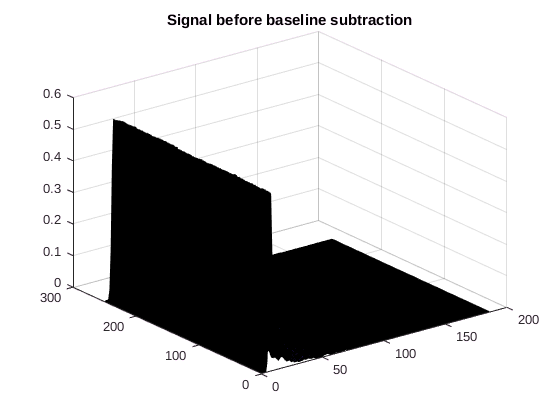

signal = []; 
for i=267:517
    data=obtain_data(i,'bb',freq);
    data=abs(data);
    signal=[signal;data];
end

figure;
surf(signal);
title('Signal before baseline subtraction');

## Plot the baseline

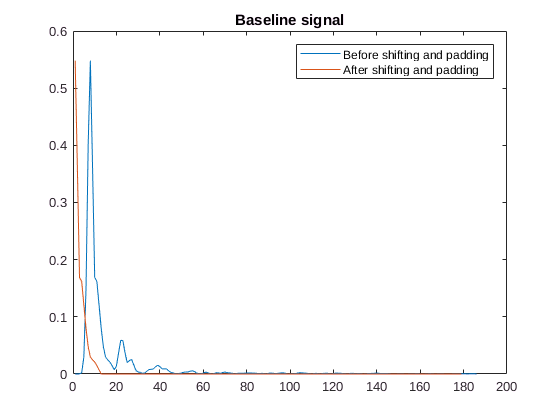

baseline=obtain_baseline('bb', freq);
figure;
plot(abs(baseline)); %Plot baseline with any shifting or padding
hold on;
[val_zero index_zero] = max(abs(baseline));
%Shift and pad baseline with zeros
baseline=baseline(index_zero:length(baseline));
baseline = [baseline(1:12) zeros(1,length(baseline)-12)];
plot(abs(baseline));
title('Baseline signal');
legend('Before shifting and padding','After shifting and padding')

## Plot the signal after baseline subtraction

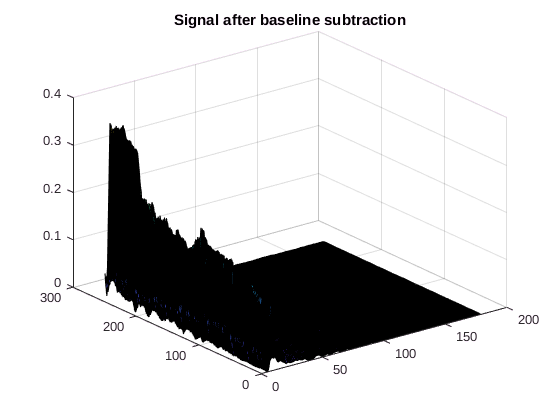

signal = []; 
peaks = [];
for i=267:517
    data=obtain_data(i,'bb',freq);
    data=data(index_zero:length(data));
    data=abs(data-baseline);
    peaks=[peaks max(data)];
    signal=[signal;data];
end

figure;
surf(signal);
title('Signal after baseline subtraction');

## Plot the peaks from the aluminum disk

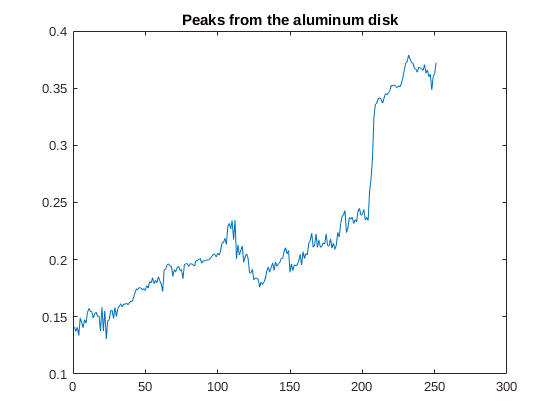

figure
plot(peaks);
title('Peaks from the aluminum disk');

## Isolate the pulse from the table

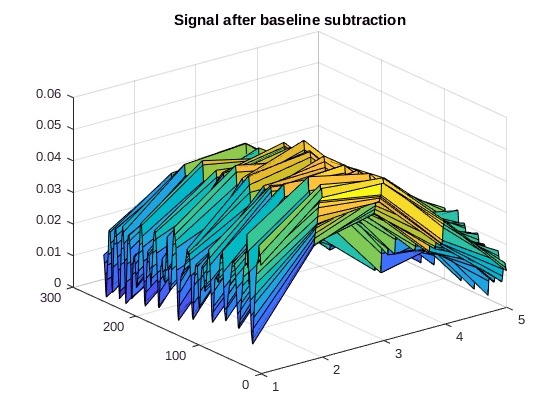

signal = []; 
peaks = [];
for i=267:517
    data=obtain_data(i,'bb',freq);
    data=data(index_zero:length(data));
    data=abs(data-baseline);
    data=data(14:18);
    peaks=[peaks max(data)];
    signal=[signal;data];
end

figure;
surf(signal);
title('Signal after baseline subtraction');

## Plot the peaks from the table 

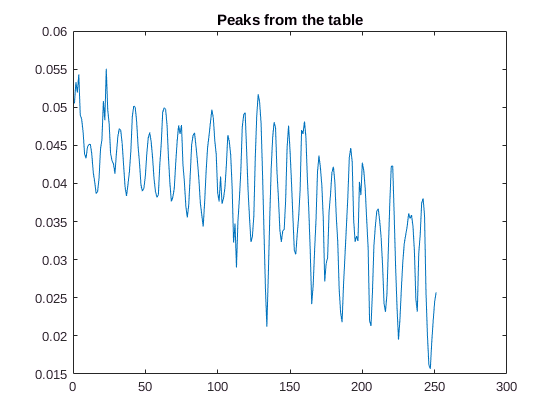

figure
plot(peaks);
title('Peaks from the table');